# **TU: ODE-IVP - Part 1**

**Numerical Programming: Y.-K. Kim**

Mod. 2024.10

# **I. 1st order ODE-IVP**

## Problem

Solve for the response (Vout) of an RC circuit with a sinusoidal input (Vin), from t=0 to 0.1 sec.

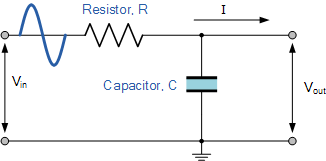

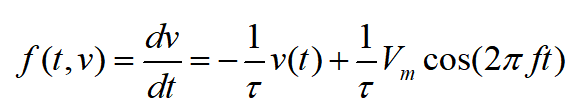

where 

RC=tau=0.01;  T=1/tau; 

f=100; Vm=1; w=2*pi*f;

## Part 1. MATLAB Tutorial

### Initial Condition

% Initial Condition
% time
a=0; b=0.1; 
h=0.001; 
t=a:h:b;
N = (b-a)/h;

% IVP-Initial Condition
v0 = 0;
y0= v0;

### Analytical Solution (Ground-truth)

The true analytical solution can be expressed as

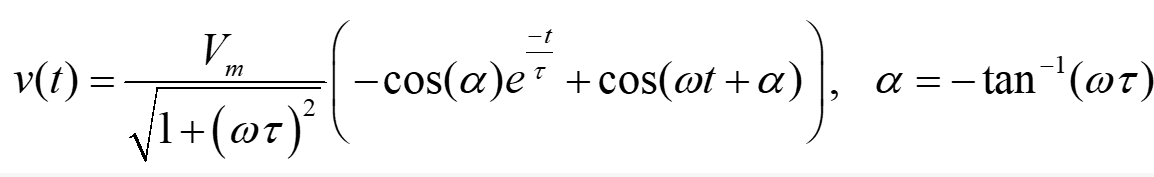

% Analytical Solution
tau=0.01; f=100; Vm=1; w=2*pi*f;

A=Vm/(sqrt(1+(w*tau)^2));
alpha=-atan(w*tau);

v_true=A*(-cos(alpha)*exp(-t/tau)+cos(w*t+alpha));



### MATLAB : ode45()

Lets define the RC circuit ODE function  f(t,v) as  odeFunc**_RC(t,v).**

*See ****Function Definition*** ***Section**** at the end of this tutorial file*


% odeFunc_RC.m

 %function dvdt = odeFunc_RC(t,v)
  %  tau=0.01; f=100; Vm=1;
   % dvdt =-v/tau + (1/tau)*Vm*cos(2*pi*f*t);
 %end


Use ode45() or other similar functions to solve.

Type  `doc ode45` in the commpand prompt to read more about this function.

%% MATLAB's function ODE45
[tmat,vmat] = ode45(@odeFunc_RC, [a b], v0);  %[a:h:b]


Plot and compare with analytical solution

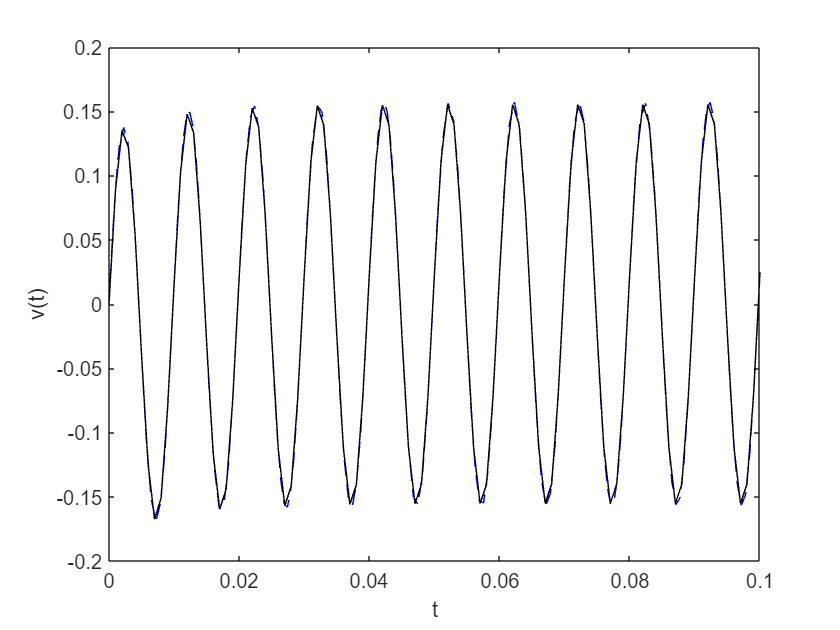

figure()
plot(tmat,vmat,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

## Exercise 

#### Exercise 1:  Euler's Explicit Method

**odeEU.m**

`[t, yE] = odeEu(@odeFunc_RC,a,b,h,y0)`

% function [x, yE] = odeEU(ODE,a,b,h,y0)

    % Variable Initialization
    N = (b-a)/h;
    yE=zeros(1,N+1);
    t=zeros(1,N+1);

    % Initial Condition
    yE(1) = y0;
    t(1)=a;
    
    % Euler Explicit ODE Method
    for i = 1:N
        t(i+1) = t(i) + h;
        yE(i+1) = yE(i) + odeFunc_RC(t(i),yE(i)) * h; 
    end

% end  % End of Function


Plot and compare with analytical solution

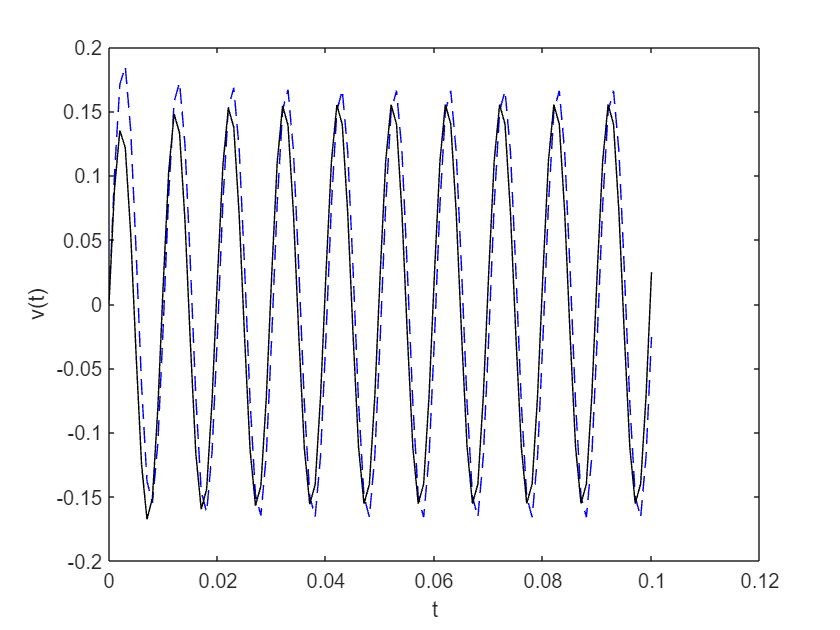

figure()
plot(t,yE,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

Also, create the function file as `odeEU.m`** . **

`> See the example code file   ``odeEU_student.m` 

[t, yE] = odeEU_student(@odeFunc_RC,a,b,h,y0);

figure()
plot(t,yE,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

#### Exercise 2: Euler's Modified Method

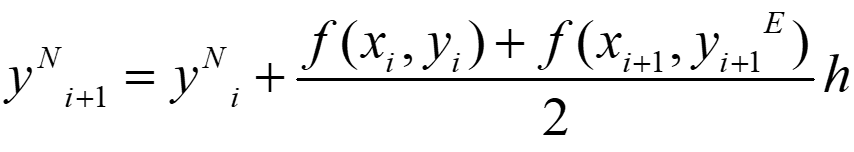

**Create odeEM_student.m**

Modify  the given template code

[t, yEM] = odeEM_student(@odeFunc_RC,a,b,h,y0);


Plot and compare with analytical solution

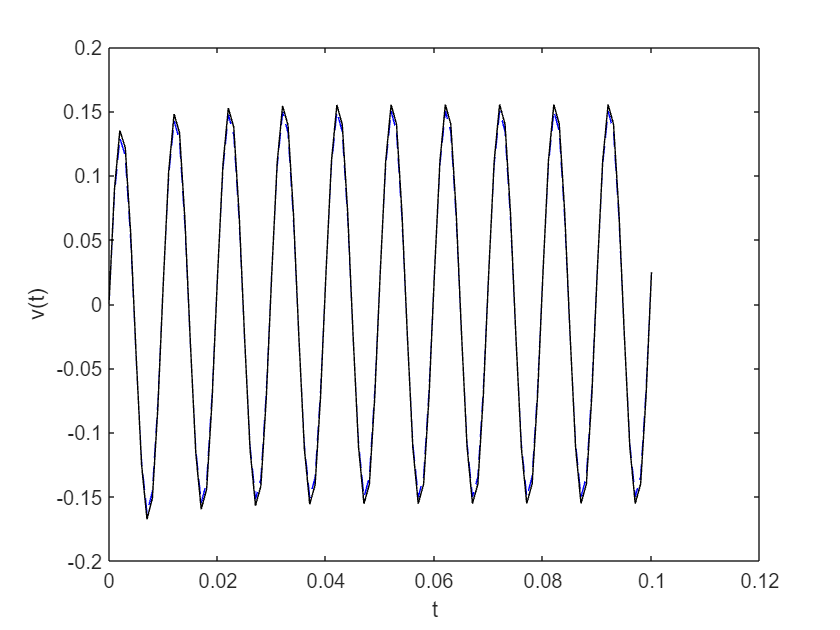

figure()
plot(t,yEM,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

#### Exercise 3: 2nd Order Runge-Kutta

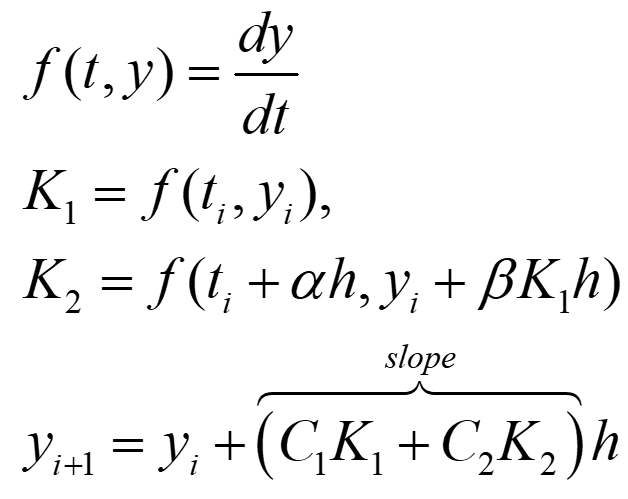

Let alpha=1, C1=0.5, C2=0.5. 

**Create odeRK2.m**

 Modify  the given template code                           

[t, yRK2] = odeRK2_student(@odeFunc_RC,a,b,h,y0);

figure()
plot(t,yEM,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

#### Exercise 4: 3th Order Runge-Kutta

**Create odeRK3.m**                      

[t, yRK3] = odeRK3_student(@odeFunc_RC,a,b,h,y0);

Plot and compare with analytical solution

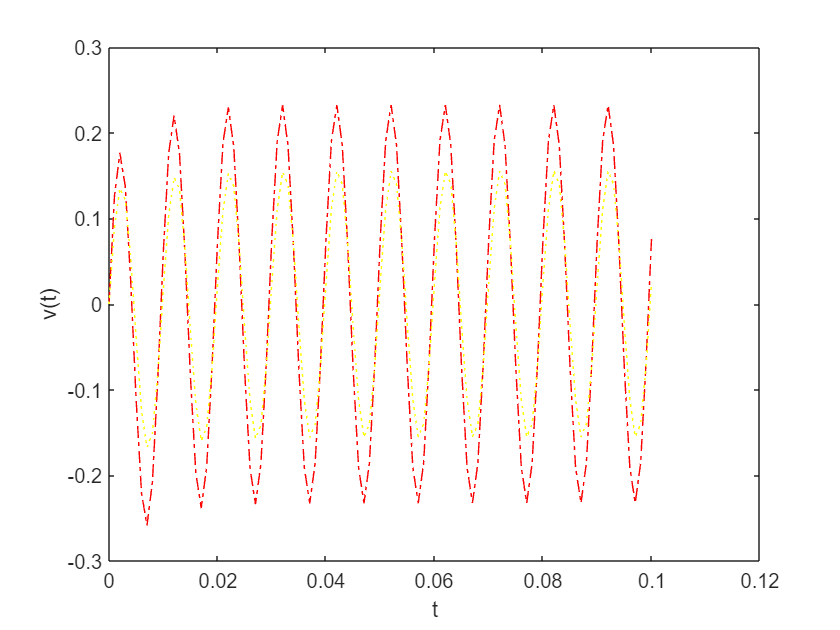

figure()
plot(t,yRK3,'-.r',t,v_true,':y')
xlabel('t'); ylabel('v(t)')

#### Exercise 5: 4th Order Runge-Kutta

**Create odeRK4.m**

[t, yRK4] = odeRK4_student(@odeFunc_RC,a,b,h,y0);

Plot and compare with analytical solution

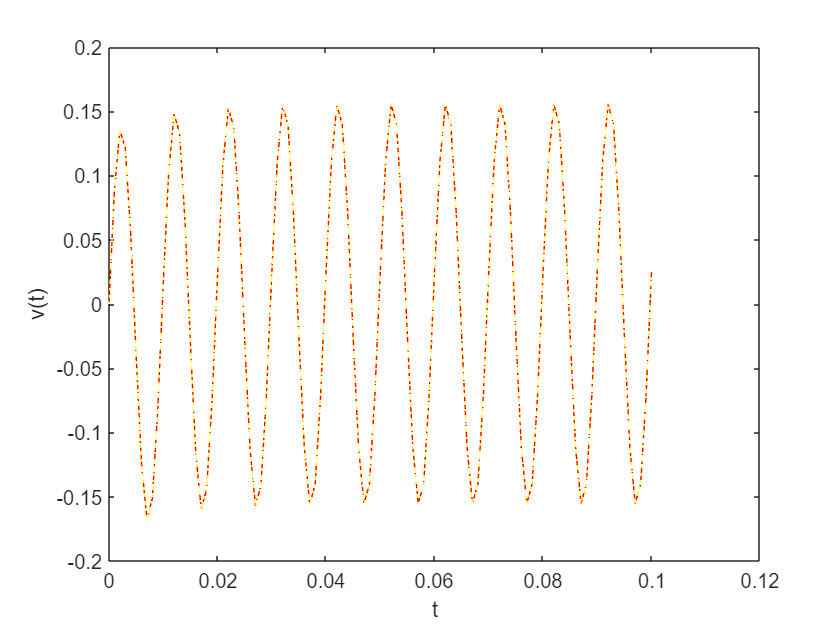

figure()
plot(t,yRK4,'-.r',t,v_true,':y')
xlabel('t'); ylabel('v(t)')

# Function Definitions

**odeFunc_RC.m**

Lets define the RC circuit ODE function  f(t,v) as  odeFunc**_RC(t,v)**

function dvdt = odeFunc_RC(t,v)
   tau=0.01; f=100; Vm=1;
   dvdt =-v/tau + (1/tau)*Vm*cos(2*pi*f*t);   
end
